# Export Networks to Simulink and Generate Code

This example shows how to export a network to Simulink, visualize the network in Simulink, and generate C code for the exported network. 

You can export a trained model to Simulink using [`exportNetworkToSimulink`](docid:nnet_ref#mw_a5041c69-27be-4aba-8c87-d6defd6649ce). You generate fixed-point C code from the exported network that you can use in embedded systems using Embedded Coder®. 

For completeness of the workflow, the example includes training and quantizing a deep neural network. If you are familiar with these steps, skip to the Export Network to Simulink and Explore Model section.

## Export Network to Simulink and Explore Model

Export the model with quantization details to Simuilnk using the [`exportNetworkToSimulink`](docid:nnet_ref#mw_a5041c69-27be-4aba-8c87-d6defd6649ce) function.

mdlInfo = exportNetworkToSimulink(netOriginal,ModelName="OriginalNetwork")

mdlInfo = struct with fields:
           ModelName: 'OriginalNetwork'
         NetworkName: 'netOriginal'
           ModelPath: 'L:\gitWork\ESWeek-Acoustic-AI-with-MBD\AcousticsAI_MBD\Ex5_Simulation'
       InputDataType: 'Inherit: auto'
     BlockParameters: dictionary (string ⟼ cell) with 6 entries
    BlockConnections: [7×2 table]
          NumInports: 1
         NumOutports: 1
          SampleTime: '-1'
            Stateful: 1
          FrameBased: 0


The top level of the generated model is a subsystem block that contains the entire network.

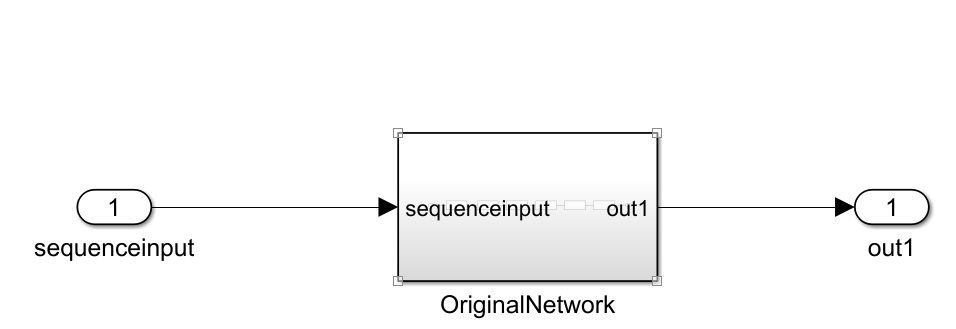

To explore the individual layer blocks for the layers in the network, double-click the subsystem block.

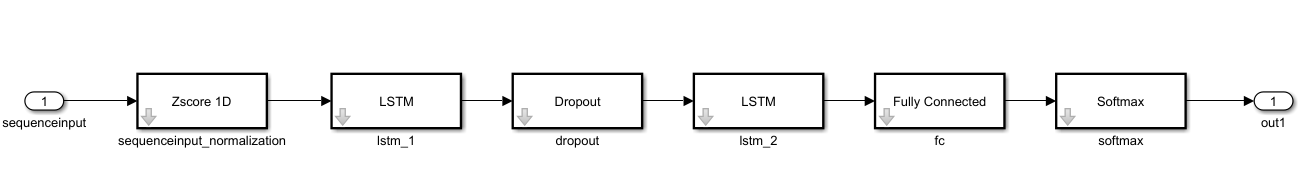

To see the internal operations of each layer block, open the subsystem by clicking the down arrow.

## Generate C Code

You can generate C code from the exported model using Simulink® Coder™ or Embedded Coder®. 

In the Apps gallery, under **Code Generation**, click **Embedded Coder**. On the **C Code** tab, click **Quick Start**.

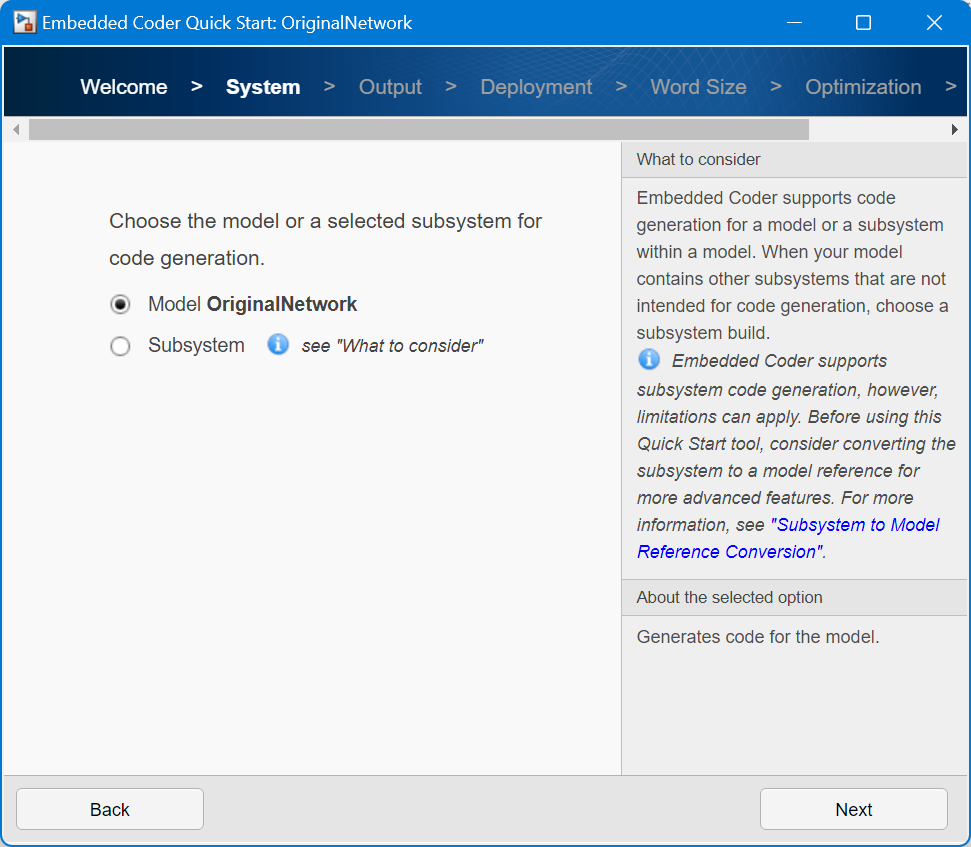

Advance through the steps of the Quick Start tool. For this example, use the default settings that are already selected. 

Return to the **C Code** tab. Click on a layer block to inspect the generated for the individual layer in the Code view next to the model.

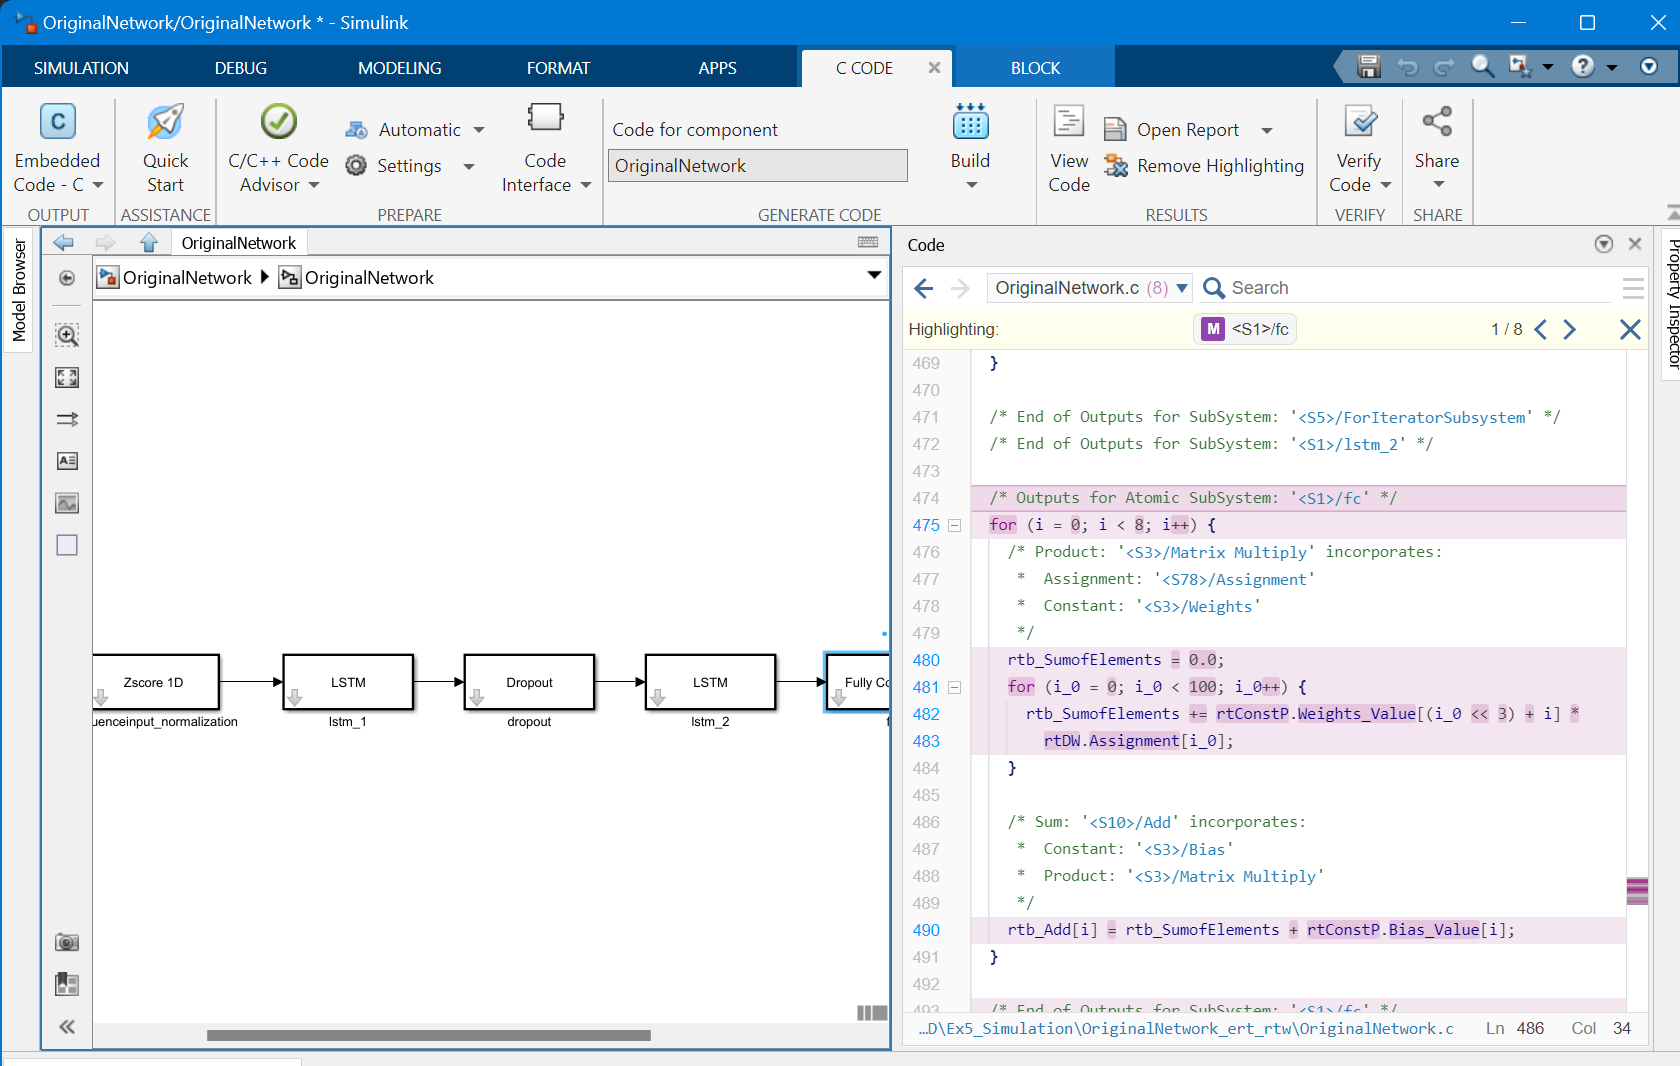

For an example of code generation for a neural network exported to Simulink that includes software-in-the-loop (SIL) testing, see [Generate Code for Battery State of Charge Estimation Using Deep Learning](docid:nnet_ug#mw_f48cbd4e-5156-468f-8ad3-0f29ef6a1642).

*Copyright 2024 The MathWorks, Inc.*